**OPTIMALNA METODA**

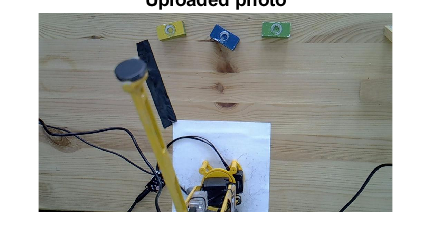


img = imread('slika_projekt.jpg');
imshow(img); title('Uploaded photo');

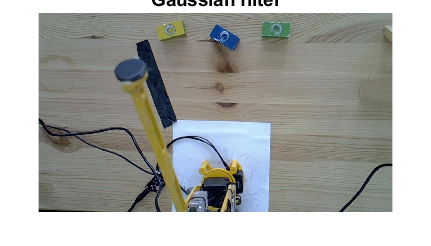



gauss_filt = fspecial('gaussian', [1,1], 5);
img_filt= imfilter(img, gauss_filt);
figure;
imshow(img_filt); title('Gaussian filter');

imwrite(img,'proba7.jpg')

%% 
img_hsv = rgb2hsv(img_filt);
img_gray = rgb2gray(img_filt);
I = img_hsv;

**Žuta**

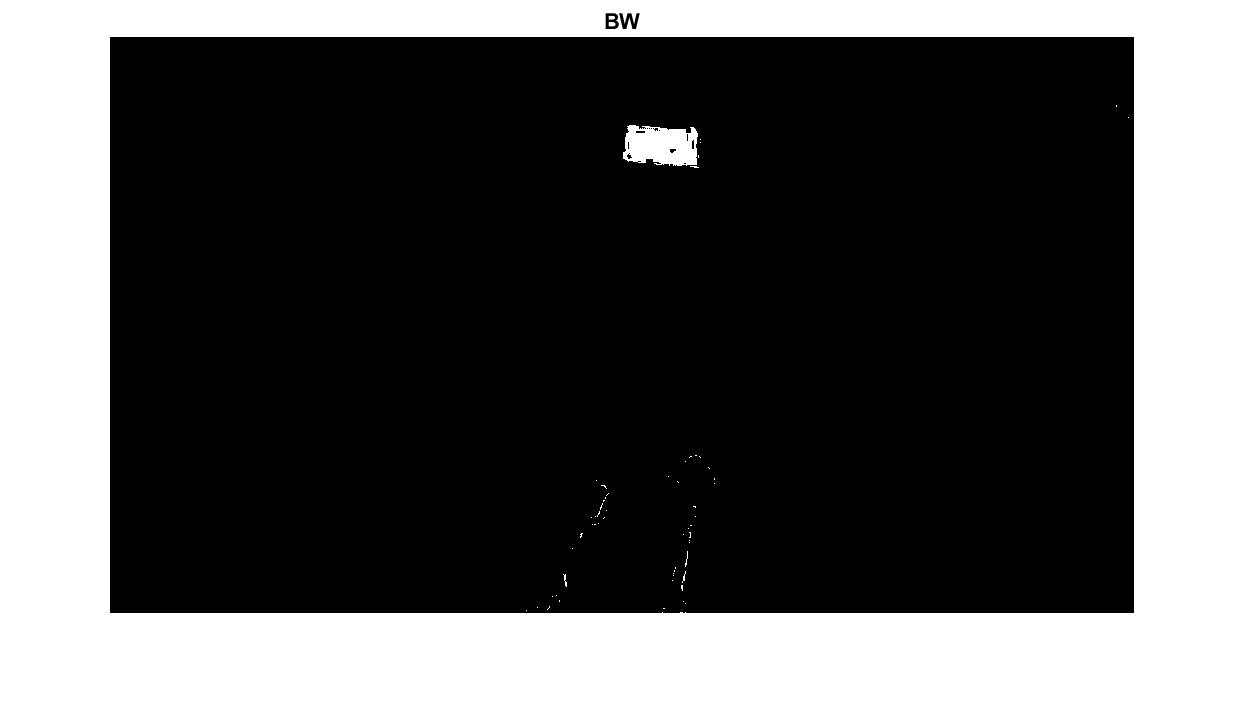

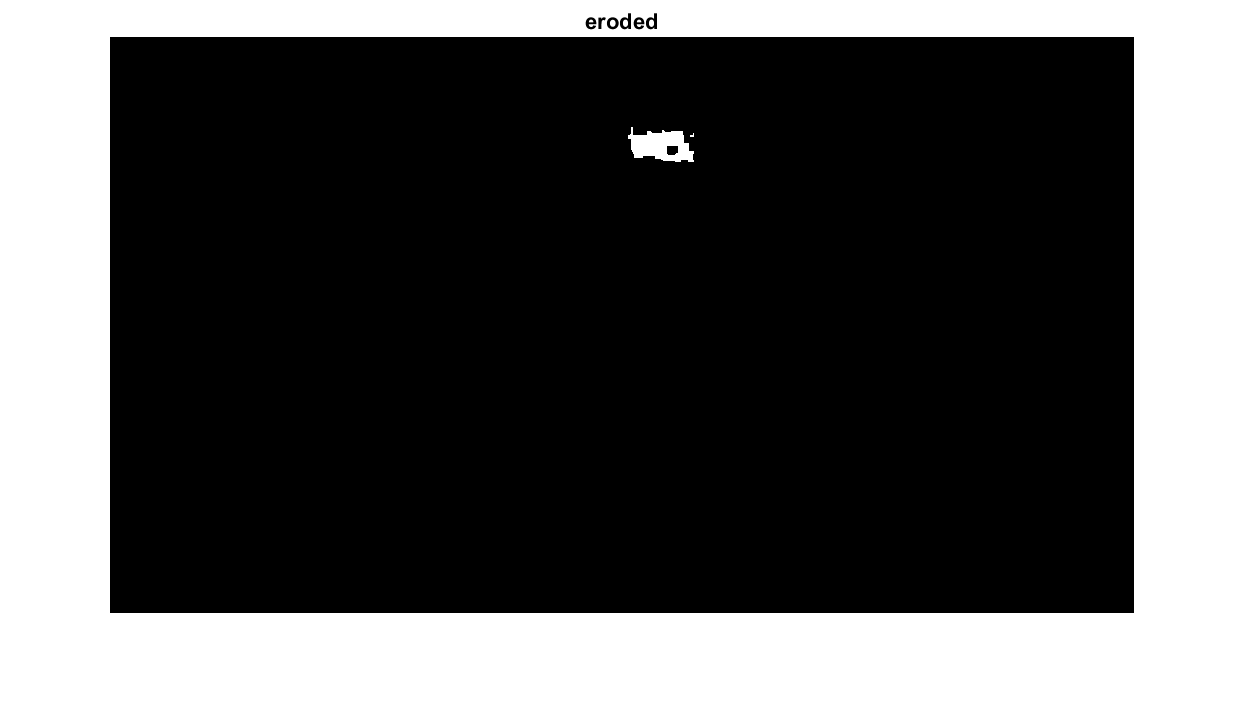

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.135;
channel1Max = 0.157;
        
% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.286;
channel2Max = 0.464;
        
% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.462;
channel3Max = 0.655;

sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
imshow(BW);title('BW')
figure;

se = strel('square', 6);
eroded = imerode(BW, se);
imshow(eroded);title('eroded');

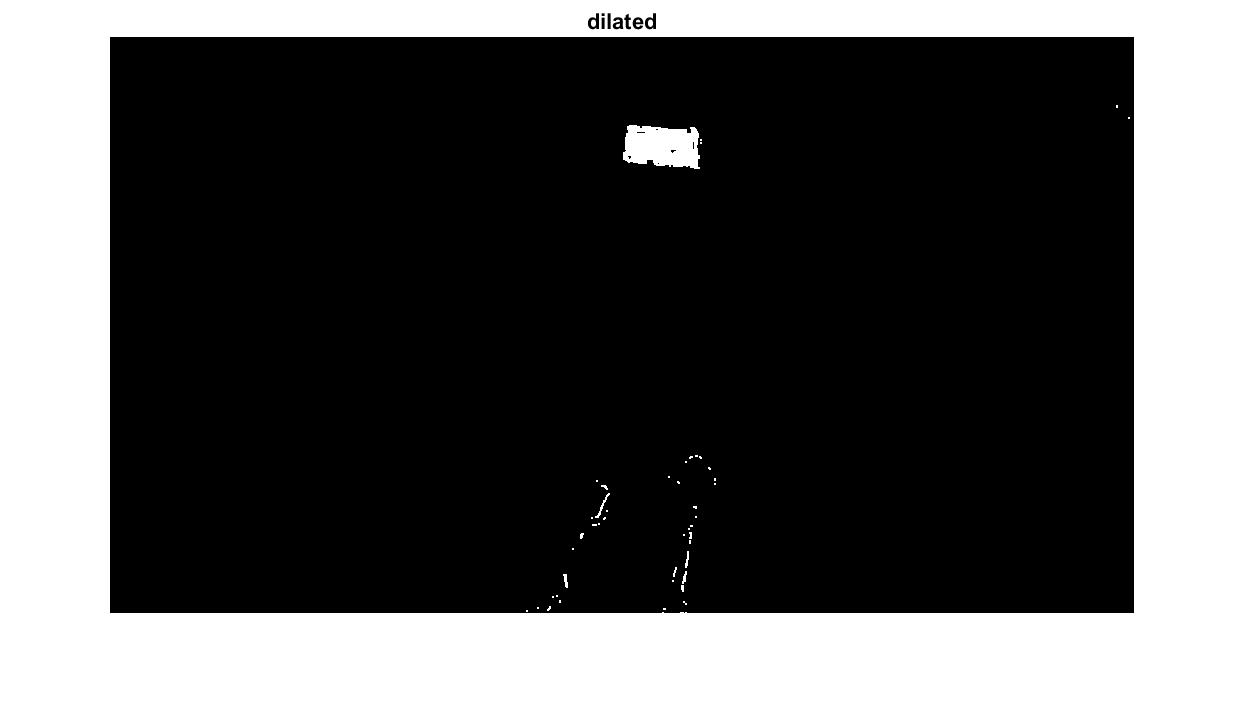

figure;
se = strel('square', 2);
dilated = imdilate(BW, se);
imshow(dilated);title('dilated')

figure;

%%----------ako eroded/dilated pomaze---------
BW= eroded;
%---------------------------------------------
        
% Initialize output masked image based on input image.
maskedRGBImage = img_filt;
        
% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        

bw_x = im2bw(BW);

bw_x = imfill(BW,'holes');
[bwLabel, num]= bwlabel(bw_x);

s=regionprops(bwLabel,'BoundingBox')

s = 2×1 struct array with fields:
    BoundingBox



center=regionprops(bwLabel,'Centroid')

center = 2×1 struct array with fields:
    Centroid


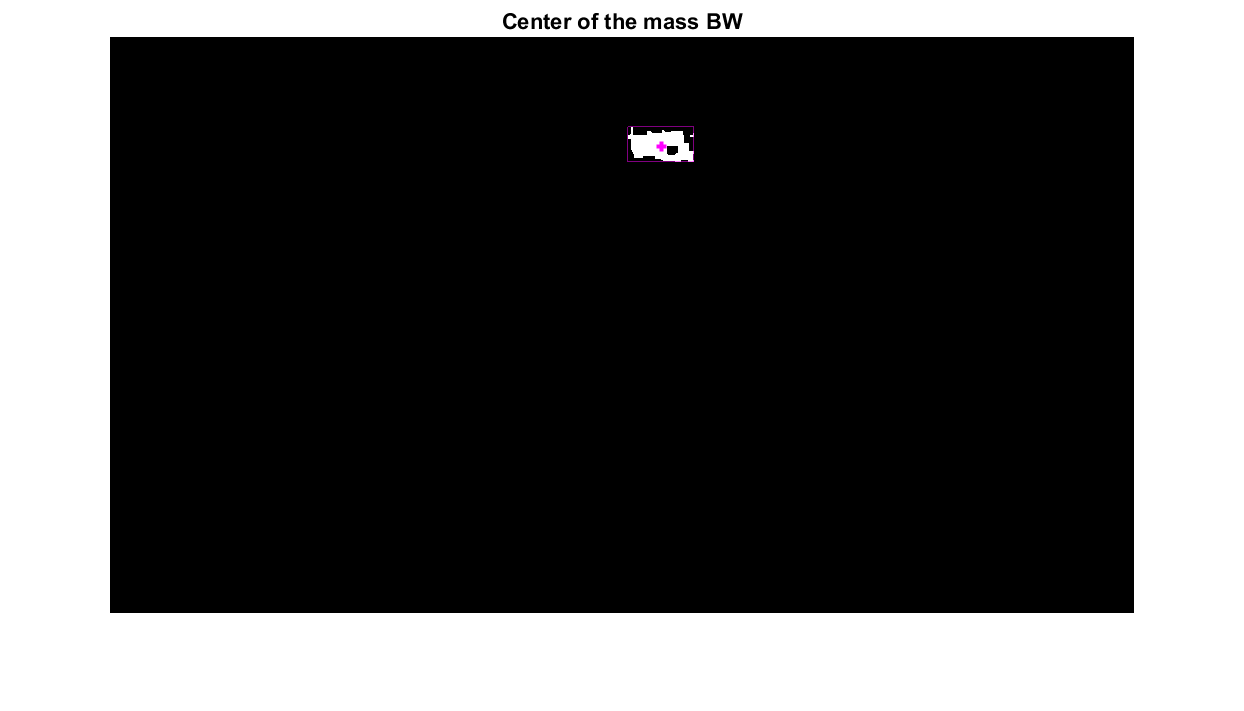

imshow(BW);
hold on
%---ENTER WICH CENTROID------
i =1;
j = 1;
%----------------------------
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass BW")
hold off

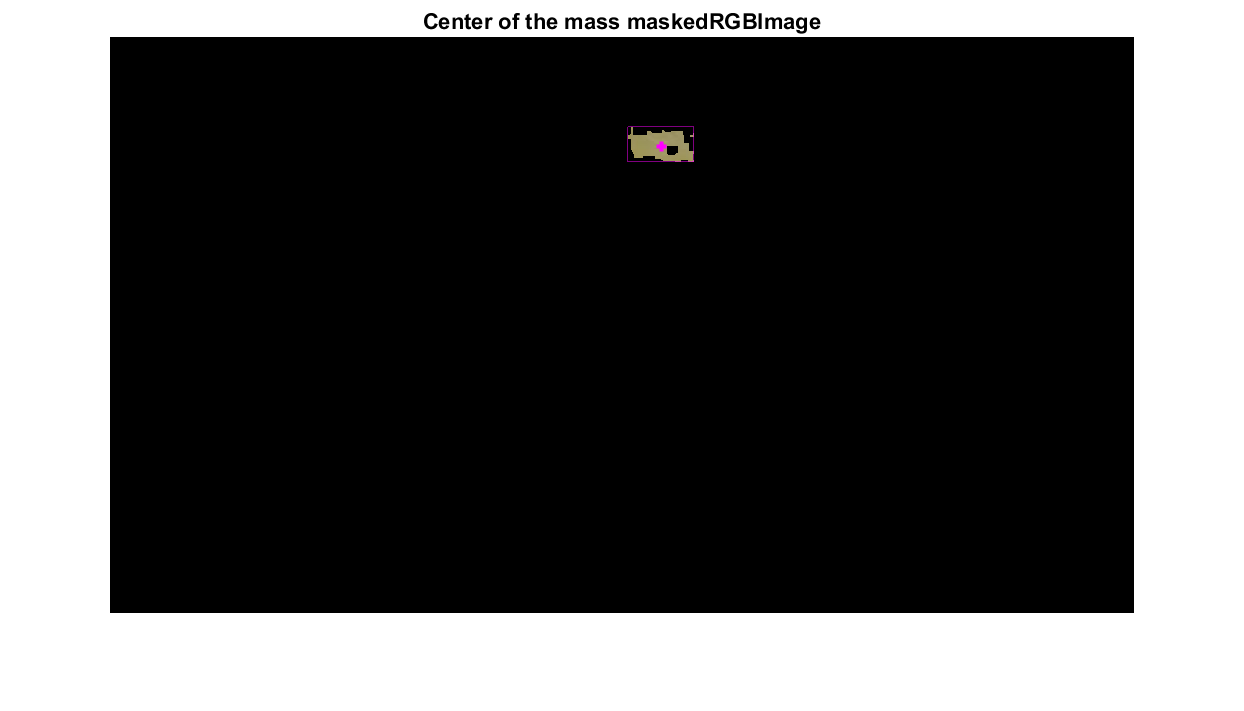


imshow(maskedRGBImage)
hold on
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass maskedRGBImage")
hold off

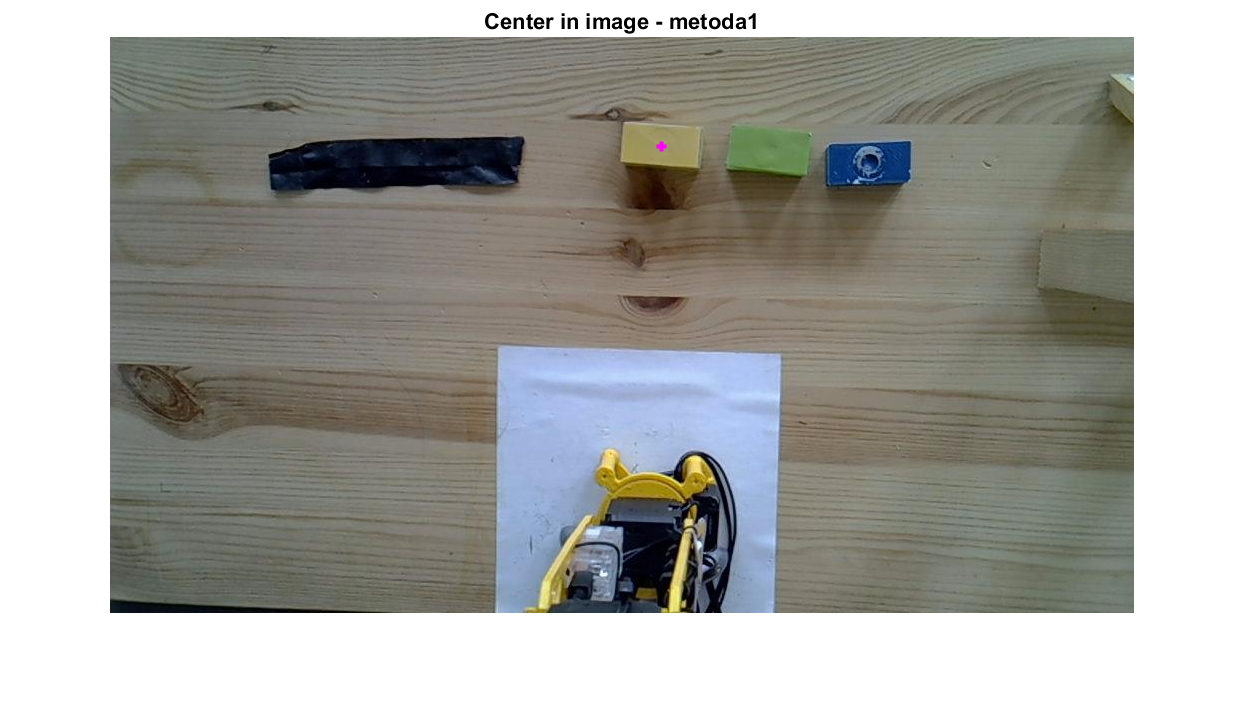


imshow(img)
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center in image - metoda1")
hold off


x_yellow = center(i).Centroid(1)

x_yellow = 552.0267

y_yellow = center(i).Centroid(2)

y_yellow = 109.7228

**Plava**

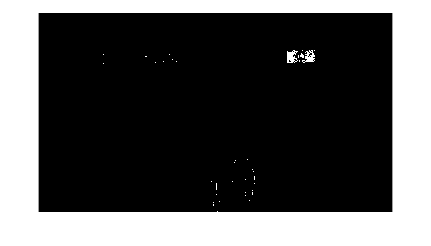

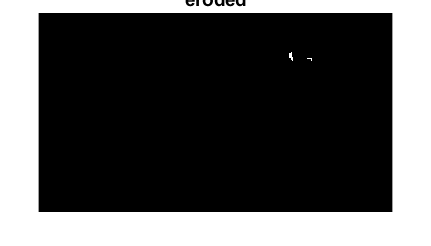

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.58;
channel1Max = 0.667;
        
% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.9;
channel2Max = 1;
        
% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.118;
channel3Max = 0.765;

sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
imshow(BW);
figure;

se = strel('square', 6);
eroded = imerode(BW, se);
imshow(eroded);title('eroded');

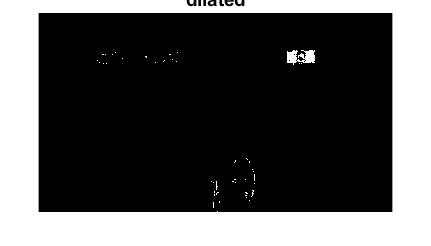

figure;
se = strel('square', 2);
dilated = imdilate(BW, se);
imshow(dilated);title('dilated')

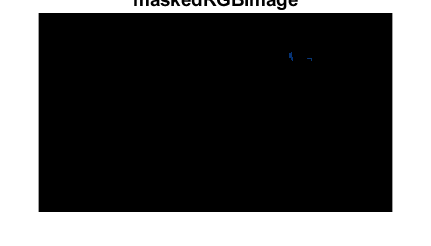

figure;

%%----------ako eroded/dilated pomaze---------
BW= eroded;
%---------------------------------------------
        
% Initialize output masked image based on input image.
maskedRGBImage = img_filt;
        
% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        
figure();imshow(maskedRGBImage);title('maskedRGBImage');

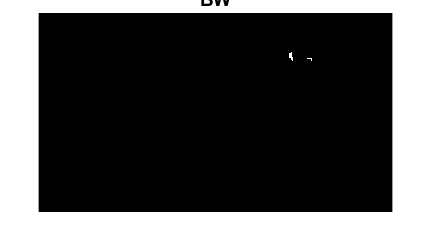

figure();imshow(BW);title('BW');


bw_x = im2bw(BW);

bw_x = imfill(BW,'holes');
[bwLabel, num]= bwlabel(bw_x);

s=regionprops(bwLabel,'BoundingBox')

s = 2×1 struct array with fields:
    BoundingBox



center=regionprops(bwLabel,'Centroid')

center = 2×1 struct array with fields:
    Centroid


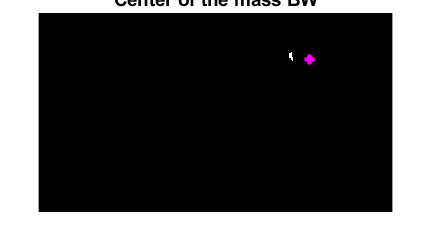

imshow(BW);
hold on
%---ENTER WICH CENTROID------
i =2;
j = 2;
%----------------------------
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass BW")
hold off

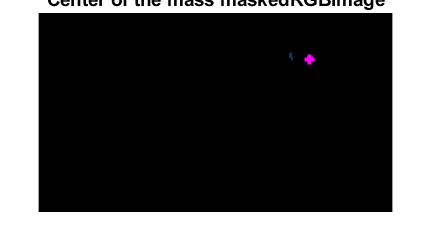


imshow(maskedRGBImage)
hold on
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass maskedRGBImage")
hold off

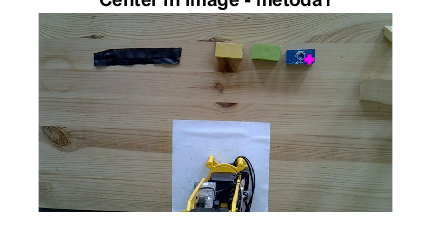


imshow(img)
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center in image - metoda1")
hold off


x_blue = center(i).Centroid(1)

x_blue = 785.2963

y_blue = center(i).Centroid(2)

y_blue = 134.6389

**Zelena**

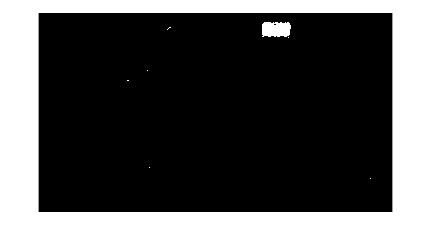

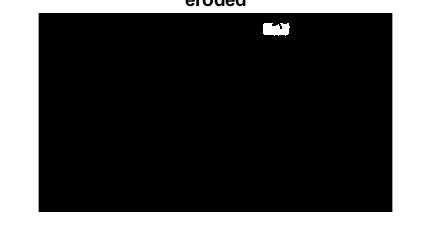

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.36;
channel1Max =0.559;
        
% Define thresholds for channel 2 based on histogram settings
channel2Min =0.19;
channel2Max =0.667;
        
% Define thresholds for channel 3 based on histogram settings
channel3Min =0.235;
channel3Max =0.733;

sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
imshow(BW);
figure;

se = strel('square', 6);
eroded = imerode(BW, se);
imshow(eroded);title('eroded');

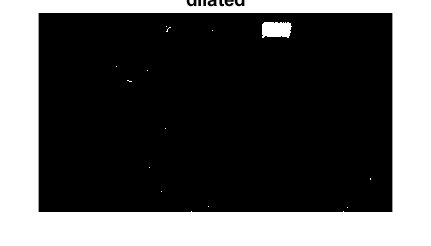

figure;
se = strel('square', 2);
dilated = imdilate(BW, se);
imshow(dilated);title('dilated')

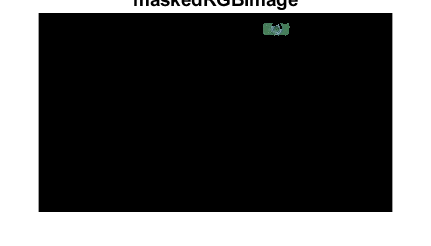

figure;

%%----------ako eroded/dilated pomaze---------
BW= eroded;
%---------------------------------------------
        
% Initialize output masked image based on input image.
maskedRGBImage = img_filt;
        
% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        
figure();imshow(maskedRGBImage);title('maskedRGBImage');

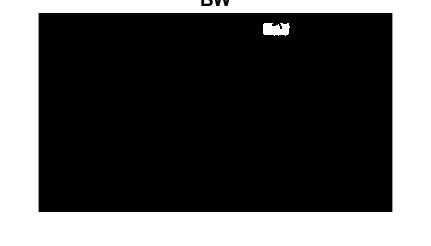

figure();imshow(BW);title('BW');


bw_x = im2bw(BW);

bw_x = imfill(BW,'holes');
[bwLabel, num]= bwlabel(bw_x);

s=regionprops(bwLabel,'BoundingBox')

s = struct with fields:
    BoundingBox: [649.5000 29.5000 78 37]



center=regionprops(bwLabel,'Centroid')

center = struct with fields:
    Centroid: [688.0660 48.2827]


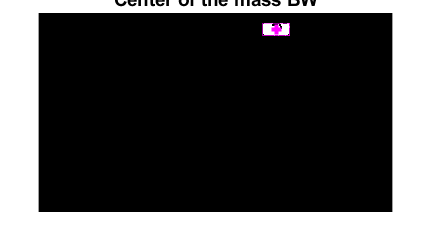

imshow(BW);
hold on
%---ENTER WICH CENTROID------
i =1;
j = 1;
%----------------------------
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass BW")
hold off

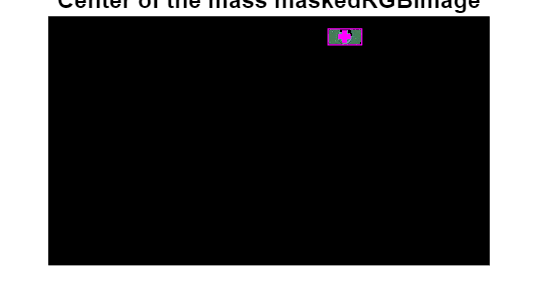


imshow(maskedRGBImage)
hold on
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass maskedRGBImage")
hold off

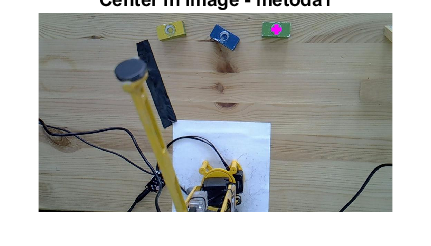


imshow(img)
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center in image - metoda1")
hold off


x_green = center(i).Centroid(1)

x_green = 688.0660

y_green = center(i).Centroid(2)

y_green = 48.2827